clc
clear 
close all

T_start = 0;
T_end = 3;

fs1 = 5e4 / 3;
Ts1 = 1/fs1;
t1 = T_start:Ts1:T_end-Ts1;

fs2 = 500;
Ts2 = 1/fs2;
t2 = T_start:3/100:T_end-Ts2;

fs3 = (fs1/fs2);
Ts3 = 1/fs3;
t3 = T_start:Ts3:T_end-Ts3;

## Continuous signal

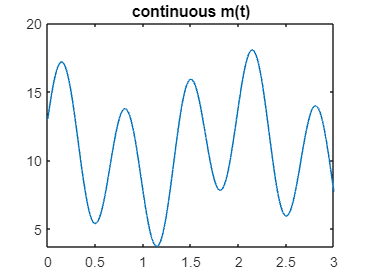

m = 10  + 5*sin(3*pi*t1) + 3*(cos(pi*t1)).^3 + sin((pi/4)*t1);
figure, plot(t1, m),title("continuous m(t)");

## Sampling

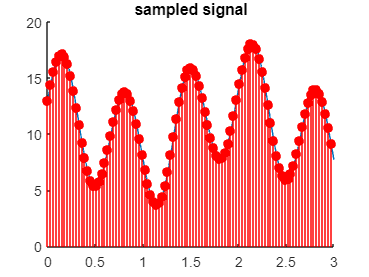

sampled_signal = zeros(length(t1)/fs2,1);
for i=1:length(sampled_signal)
    sampled_signal(i) = m(fs2*(i-1) + 1);
end
figure,
hold on
plot(t1, m),
stem(t3, sampled_signal,'filled','Color','r');
title("sampled signal")
hold off;

## Quantizing

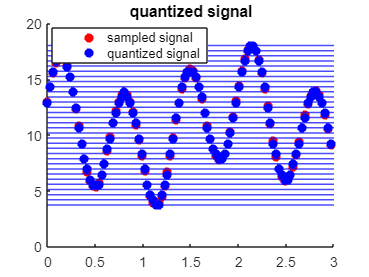

N=32;

% diffrence between Quantization levels
d = (max(sampled_signal)-min(sampled_signal))/(N-1);

quantized_signal = zeros(length(sampled_signal), 3);
for i=1:length(sampled_signal) 

    n = floor((sampled_signal(i)-min(sampled_signal))/d + 0.5);
    if (sampled_signal(i)<0)
        n = 0;
    end
    
    quantized_signal(i,1) = n*d + min(sampled_signal);          % quantized signal
    quantized_signal(i,2) = n;                                  % digit
    quantized_signal(i,3) = 2*n - 31;                           % modulation amp

end

figure, 
hold on
title("quantized signal");
stem(t3, sampled_signal,'filled','Color','r','LineStyle', 'none','LineWidth', 0.1);
stem(t3, quantized_signal(:,1),'filled','Color','b','LineStyle', 'none','LineWidth',0.1);
for i=0:31
    v = i*d + min(sampled_signal);
    yline(v, 'b', 'LineWidth', 1);
end
legend('sampled signal','quantized signal','Location', 'best');
hold off;

## Modulation

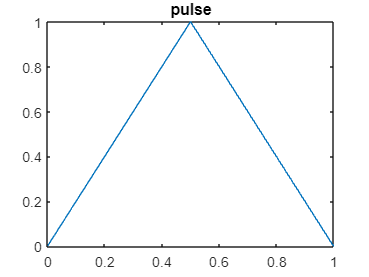

fs4 = 1e3;
Ts4 = 1/fs4;
t4 = 0:Ts4:100-Ts4;
t5 = 0:Ts4:1-Ts4;

load p.mat;
pulse = p;
figure, plot(t5, pulse), title("pulse");


E_pulse = sum(pulse.^2)

E_pulse = 333.3340

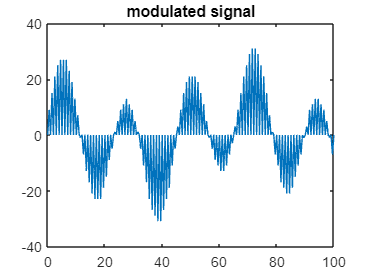


modulated_signal = [];
for i=1:length(quantized_signal)
    modulated_signal = [modulated_signal , quantized_signal(i,3)*pulse];
end
figure, plot(t4, modulated_signal), title("modulated signal");

## Add Noise

E_modulated_signal = sum(modulated_signal.^2)/length(modulated_signal)

E_modulated_signal = 92.7602

SNR = 10^(2/10);
E_noise = E_modulated_signal/SNR

E_noise = 58.5277

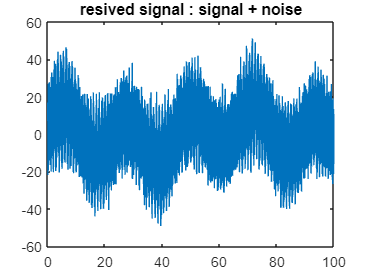

var_noise = E_noise;
noise = sqrt(var_noise)*randn(1,length(t4));

resived_signal = modulated_signal + noise;
plot(t4, resived_signal), title("resived signal : signal + noise");

## Resive

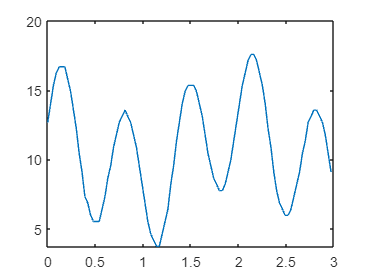


E = zeros(length(resived_signal)/fs4,1);

for i=1:100
    E(i) = sum(resived_signal((i-1)*fs4 + 1:i*fs4).*pulse)/E_pulse;
end

desierd_signal_amplitude = (2*floor(((E+1)/2)+0.5)-1);
desierd_signal_digit= ((desierd_signal_amplitude+31)/2);
desierd_signal = desierd_signal_digit*((max(sampled_signal)-min(sampled_signal))/32)+min(sampled_signal);
figure, plot(t3, desierd_signal)

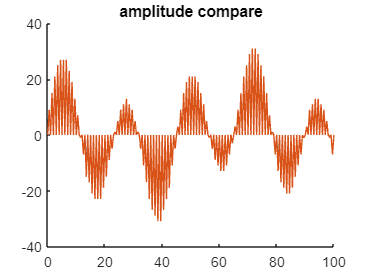


modulated_signal_resived = [];
for i=1:length(quantized_signal)
    modulated_signal_resived = [modulated_signal_resived ,desierd_signal_amplitude(i)*pulse];
end

figure, hold on ,title("amplitude compare");
plot(t4,modulated_signal);
plot(t4,modulated_signal_resived);
hold off


% error = sum(modulated_signal_resived - modulated_signal)/(100*sum(pulse))
% error = sum(desierd_signal_amplitude - quantized_signal(:,3))/100
% error = sum(desierd_signal - quantized_signal(:,1))/100
error = sum((desierd_signal_digit - quantized_signal(:,2)).^2) /100

error = 0.0200

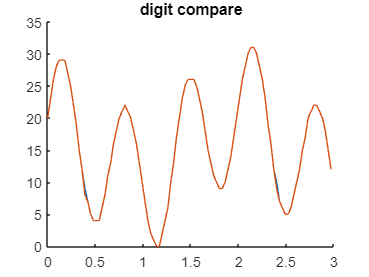


% gray coding
transmit_digits = quantized_signal(:,2);
resive_degits = desierd_signal_digit;

figure, hold on , title("digit compare") ;
    plot(t2, transmit_digits);
    plot(t2, resive_degits);
hold off


gray = [[0, 0, 0, 0, 0];
        [0, 0, 0, 0, 1];
        [0, 0, 0, 1, 1];
        [0, 0, 0, 1, 0];
        [0, 0, 1, 1, 0];
        [0, 0, 1, 1, 1];
        [0, 0, 1, 0, 1];
        [0, 0, 1, 0, 0];
        [0, 1, 1, 0, 0];
        [0, 1, 1, 0, 1];
        [0, 1, 1, 1, 1];
        [0, 1, 1, 1, 0];
        [0, 1, 0, 1, 0];
        [0, 1, 0, 1, 1];
        [0, 1, 0, 0, 1];
        [0, 1, 0, 0, 0];
        [1, 1, 0, 0, 0];
        [1, 1, 0, 0, 1];
        [1, 1, 0, 1, 1];
        [1, 1, 0, 1, 0];
        [1, 1, 1, 1, 0];
        [1, 1, 1, 1, 1];
        [1, 1, 1, 0, 1];
        [1, 1, 1, 0, 0];
        [1, 0, 1, 0, 0];
        [1, 0, 1, 0, 1];
        [1, 0, 1, 1, 1];
        [1, 0, 1, 1, 0];
        [1, 0, 0, 1, 0];
        [1, 0, 0, 1, 1];
        [1, 0, 0, 0, 1];
        [1, 0, 0, 0, 0];];

transmit_array = [];
resive_array = [];
for i=1:length(transmit_digits)
    transmit_array = [transmit_array, gray(transmit_digits(i)+1 , :)];
    resive_array = [resive_array, gray(resive_degits(i)+1 , :)];
end

error = sum(abs(transmit_array - resive_array))/length(transmit_array)

error = 0.0040

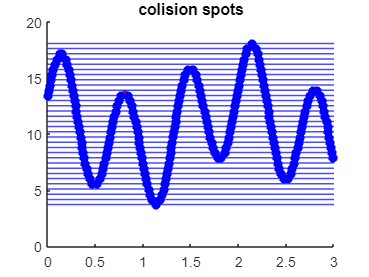

N=32;

% diffrence between Quantization levels
d = (max(m)-min(m))/(N-1);

quantized_m = zeros(length(m), 3);
colision_time = [];
colision_value = [];
for i=1:length(m) 
    n = floor((m(i)-min(m))/d); 
    quantized_m(i,1) = n*d + min(m);          % quantized signal
    quantized_m(i,2) = n;                     % digit
    quantized_m(i,3) = 2*n - 31;              % modulation amp
    if i > 1
        if (quantized_m(i,2) ~= quantized_m(i-1,2)) || (m(i) == min(m))
            colision_time = [colision_time,(t1(i)+t1(i-1))/2];
            colision_value = [colision_value,(m(i)+m(i-1))/2];
        end
    end
end

figure, 
hold on
title("colision spots");
plot(t1 , m,'Color','r','LineWidth', 2);
stem(colision_time, colision_value,'filled','Color','b','LineStyle', 'none','LineWidth',0.1);
for i=0:31
    v = i*d + min(m);
    yline(v, 'b', 'LineWidth', 1);
end
hold off;

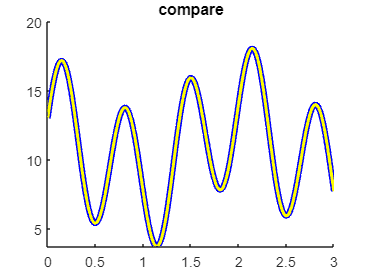



m_interpolated = spline(colision_time, colision_value, t1);

figure, title("compare")
hold on
plot(t1 , m,'Color','b','LineWidth', 4);
plot(t1 , m_interpolated,'Color','y','LineWidth', 2);
hold off;


error = sum((m-m_interpolated).^2)/length(m)

error = 5.4389e-07